# Hankel Matrix Completion

## Experimenting with LTI's without input

First we get an intuition of state space definition without input. We deal with discrete systems, since we are interested in data sampled at specific time points in history.

% statenum states, outputnum outputs, 0 input
statenum = 100;
outputnum = 1;

state_space = drss(statenum,outputnum,0)

state_space =
 
  A = 
                 x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13         x14         x15         x16         x17         x18         x19         x20         x21         x22         x23         x24         x25         x26         x27         x28         x29         x30         x31         x32         x33         x34         x35         x36         x37         x38         x39         x40         x41         x42         x43         x44         x45         x46         x47         x48         x49         x50         x51         x52         x53         x54         x55         x56         x57         x58         x59         x60         x61         x62         x63         x64         x65         x66         x67         x68         x69         x70         x71         x72         x73         x74         x75         x76         x77         x78         x79         x80         x

state_space_properties(state_space)

State-space properties: 
    "Number of states: 100"
    "Number of inputs: 0"
    "Number of outputs: 1"

State-space dimensions: 
    "A_rows:100"    "A_cols:100"
    "B_rows:100"    "B_cols:0"  
    "C_rows:1"      "C_cols:100"
    "D_rows:1"      "D_cols:0"  

Max absolute eigen value: 0.99011
Eigen values of A: 
    0.8910
    0.8910
    0.9901
    0.9196
    0.8679
    0.8450
    0.8450
    0.8152
    0.7860
    0.7608
    0.7608
    0.7299
    0.7299
    0.6346
    0.6346
    0.5671
    0.5671
    0.5486
    0.9504
    0.9504
    0.5078
    0.4601
    0.4601
    0.4920
    0.4431
    0.4122
    0.9470
    0.9371
    0.9272
    0.9268
    0.3995
    0.8976
    0.3782
    0.3364
    0.3018
    0.3018
    0.6632
    0.6632
    0.8230
    0.7287
    0.7287
    0.2386
    0.2298
    0.2285
    0.2285
    0.7768
    0.7688
    0.1516
    0.1377
    0.1377
    0.1144
    0.0922
    0.3040
    0.3040
    0.7313
    0.7368
    0.0548
    0.1367
    0.1367
    0.1582
    0.1582
    0.0008

Now we create a set of outputs, with x(0) = x_0 != 0 (since we dont have an input and thus if the state is the zero vector the transfer function will not do anything to the state)

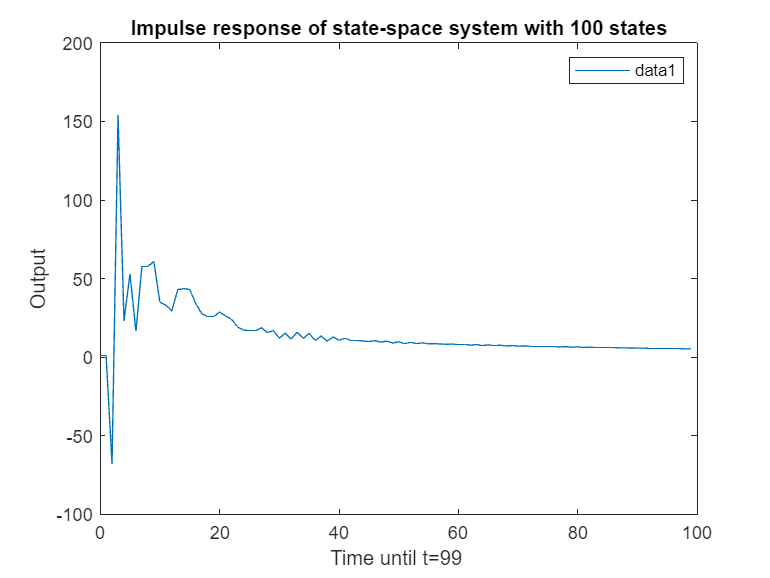

maxTime = 100;

state_space_plotter(state_space,maxTime);

Notice that its possible for one of the eigenvalues to be exactly 1, which is neither stable nor unstable (marginally stable). Using the drss function we can generate many different kinds of discrete-time state-space systems that are stable. In the plot we observe that after a long enough time the impulse response stabilizes.

## Experimenting with LTI's with input

We can also generate an LTI with an input vector upon which a transformation B and D have an effect on the state change and output. We can have a single-input or multi-input.

% statenum states, outputnum outputs, inputnum input
statenum = 100;
outputnum = 2;
inputnum = 1;
maxTime = 100;

state_space = drss(statenum,outputnum,inputnum);
state_space_properties(state_space);

State-space properties: 
    "Number of states: 100"
    "Number of inputs: 1"
    "Number of outputs: 2"

State-space dimensions: 
    "A_rows:100"    "A_cols:100"
    "B_rows:100"    "B_cols:1"  
    "C_rows:2"      "C_cols:100"
    "D_rows:2"      "D_cols:1"  

Max absolute eigen value: 1
Eigen values of A: 
    0.9491
    0.9491
    0.8292
    0.8292
    0.8886
    0.8886
    0.8246
    0.8246
    1.0000
    0.9692
    0.9857
    0.7547
    0.7547
    0.9570
    0.9474
    0.9345
    0.7767
    0.7767
    0.8612
    0.8612
    0.8592
    0.8592
    0.9371
    0.8562
    0.9278
    0.9292
    0.8654
    0.8888
    0.7931
    0.6240
    0.6240
    0.6797
    0.6797
    0.8251
    0.7183
    0.7420
    0.6289
    0.7159
    0.5759
    0.5759
    0.4565
    0.4565
    0.4636
    0.4636
    0.5388
    0.6242
    0.4534
    0.4534
    0.5027
    0.4943
    0.6162
    0.4709
    0.4491
    0.5956
    0.5956
    0.5754
    0.3104
    0.3104
    0.4167
    0.4064
    0.5202
    0.3075
    0

state_space_plotter(state_space,maxTime);

## Experimenting with Hankel Matrices

## Experimenting with Hankel Matrix Completion